# Multiclass Support Vector Classification

An example for 2D visual classification of multiclass SVM.

Written by **Junhong Zhang**, SZU, with **Matlab R2020a.**

% Initialization
clc;
clear;
close;
rng default;
point_num = 250;
nClass = 3;
X = 10 * rand(point_num, 2) - 5;

## Non-linear classification for multiclassification

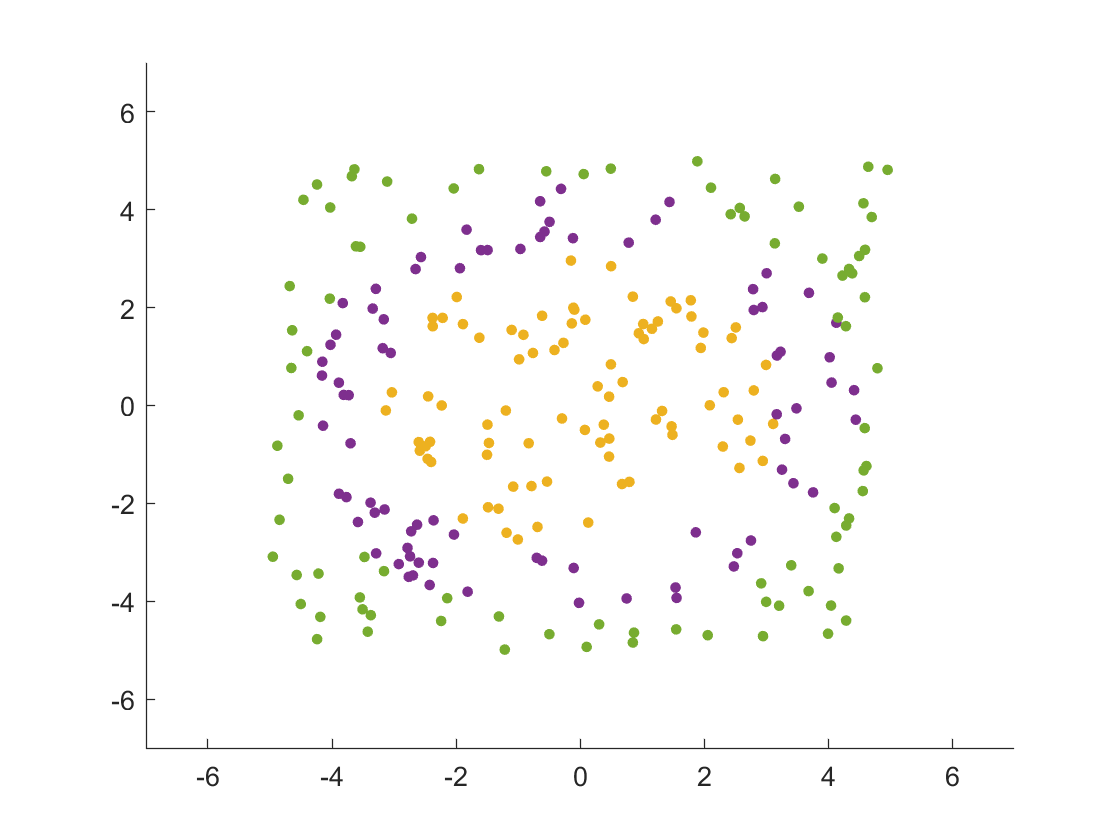

% prepare the data
fVal = X(:, 1).^2 + X(:, 2).^2;

Y1 = fVal < 10;
Y2 = 10 <= fVal & fVal < 20;
Y3 = fVal >= 20;

X1 = X(Y1, :);
X2 = X(Y2, :);
X3 = X(Y3, :);

Y = [Y1(Y1 == 1); Y2(Y2 == 1) + 1; Y3(Y3 == 1) + 2];
X = [X1; X2; X3];


% preview of data
figure;
hold on;
scatter(X1(:, 1), X1(:, 2), 16, [0.9290 0.6940 0.1250], 'filled');
scatter(X2(:, 1), X2(:, 2), 16, [0.4940 0.1840 0.5560], 'filled');
scatter(X3(:, 1), X3(:, 2), 16, [0.4660 0.6740 0.1880], 'filled');
axis([-7, 7, -7, 7]);

clear Y1 Y2 Y3 fVal;

% set parameters of SVM
params.c = 3;
params.gamma = 0;
params.d = 2;

% train multiclass SVM
tic;
models = SVM_train_multiclass(Y, X, params, 'poly');
toc;

Elapsed time is 0.058835 seconds.


[~, acc] = SVM_predict_multiclass(X, models, Y);
disp("Training accuracy (%):"); disp(100*acc);

Training accuracy (%):
   99.2000



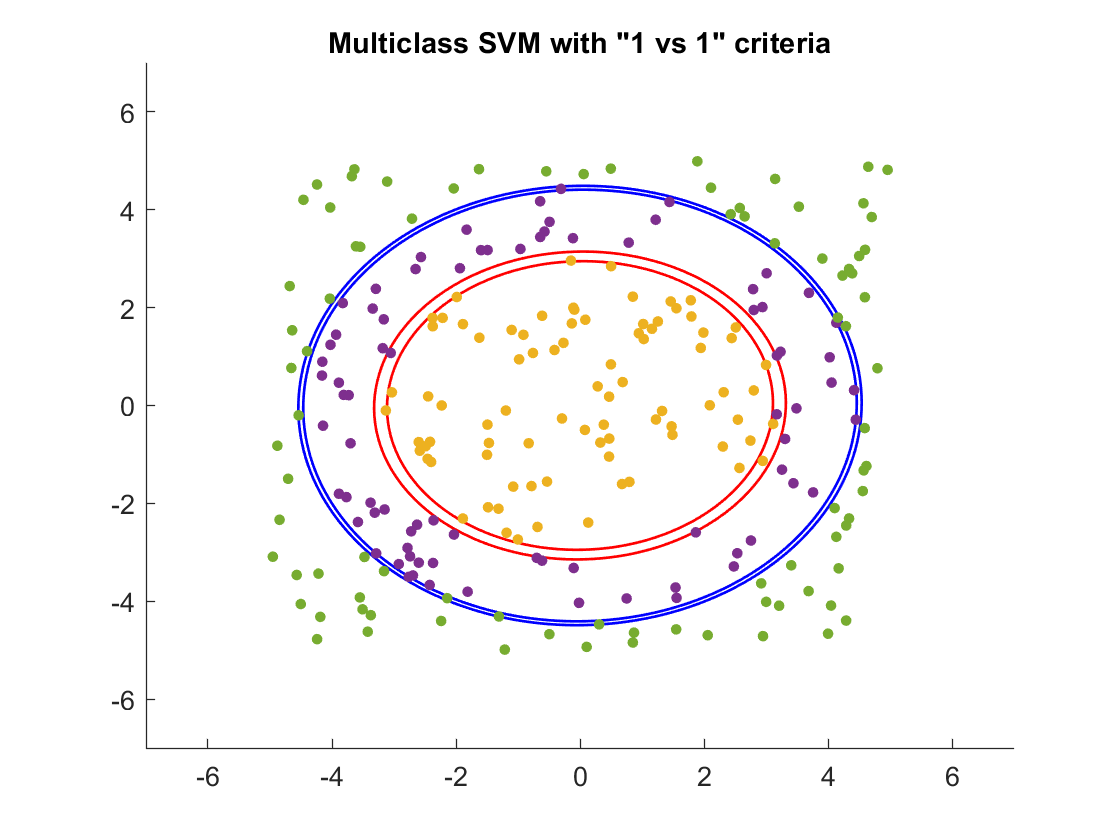

step = 100;
grid_x = linspace(-7, 7, step);
grid_y = linspace(-7, 7, step);
[gridX, gridY] = meshgrid(grid_x, grid_y);
gridZ = zeros(step, step, nClass);
clear grid_x grid_y;

XY = [gridX(:), gridY(:)];
for k = 1:nClass
    grid_z = SVM_predict(XY, models(k));
    gridZ(:, :, k) = reshape(grid_z, [step, step]);
end

figure;
hold on;
contour(gridX, gridY, gridZ(:, :, 1), [-1, 1], "r", 'LineWidth', 1);
contour(gridX, gridY, gridZ(:, :, 3), [-1, 1], 'b', 'LineWidth', 1);
scatter(X1(:, 1), X1(:, 2), 16, [0.9290 0.6940 0.1250], 'filled');
scatter(X2(:, 1), X2(:, 2), 16, [0.4940 0.1840 0.5560], 'filled');
scatter(X3(:, 1), X3(:, 2), 16, [0.4660 0.6740 0.1880], 'filled');
title('Multiclass SVM with "1 vs 1" criteria');